# 自动生成龙德投标结果分析表（无需）

clear;clc;
% 自动提取关键信息
dir_pdf = '\\longde\longde\008-投标中心\006-数据分析中心\招标文件PDF汇总\';
name = '东莞市麻涌镇特色精品示范村工程-麻一村（二坊道路升级改造）.pdf';
path_pdf = [dir_pdf, name];
[project_info, pdfstr] = GetPdfContent(path_pdf);
project_name = name(1 : end-4); 
h_bid = project_info.("h值");
Rp_bid = project_info.("下浮率");
M_bid = project_info.("最高报价");
qualification = project_info.("资质要求");
project_address = project_info.("镇区");
bid_time = project_info.("开标时间");
bid_address = project_info.("开标地点");
bid_method = project_info.("投标方法");
bid_type = project_info.("标书类型");
% 预测下浮率


zb_xlsx = readtable('\\longde\longde\008-投标中心\006-数据分析中心\分析结果汇总\zb.xlsx', 'VariableNamingRule', 'preserve');
Rps = zb_xlsx.("预测下浮率");
Project_names = zb_xlsx.("工程名称");
pos_index = nan;
for i = 1:length(Project_names)
    if strcmp(project_name, Project_names{i})
        pos_index = i;
        break;
    end
end
Rp_pre = Rps(pos_index);
P_pre = M_bid * (1 - Rp_pre);
% 读取投标数据
path_xlsx = ['\\longde\longde\008-投标中心\006-数据分析中心\投标数据Excel文件汇总\', project_name, '.xlsx'];
try
    file = readtable(path_xlsx, 'Sheet', '开标信息', 'VariableNamingRule', 'preserve');
catch ME
    file = readtable(path_xlsx, 'Sheet', 1, 'VariableNamingRule', 'preserve');
end
file_sort = sortrows(file, 2);
company_name = file_sort.("企业名称");
Gn = file_sort.("投标报价");
Ps = 1 - Gn / M_bid;
% 去掉首尾均值
P = mean(Gn(2 : end-1));
R = 1 - P / M_bid;
err_real = Gn - P;
err_abs = abs(err_real);
[~, indx] = min(err_abs);
% 低于 P 的最高值
if err_real(indx) > 0
    indx = indx - 1;
end
if indx < 1
    indx = 1;
end
company_name_win = company_name(indx);
price_win = Gn(indx)

price_win = 7.7333e+05

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 画图
fig = figure;
% set(fig, 'Position', [100, 100, 430, 405]);
stem(err_real, 'LineWidth', 1.5);
xlim([0.5, 15.5]);
hold on
stem(indx, err_real(indx), 'MarkerFaceColor', 'red');
text(indx, 0, num2str(err_real(indx), '%.2f'), 'FontSize', 6, 'Rotation', 90);
plot([1, 15], ones(1, 2) * (P_pre - P), 'LineWidth', 1.5);
text(10, (P_pre - P) * 1.1, num2str(P_pre - P, '%.2f'), 'FontSize', 6);
hold off
ylabel('投标价和均价差距');
title(project_name);
set(gca, 'FontSize', 6, 'LooseInset', [0 0 0.01 0.01]);
set(gca, 'XTick', 1:15, 'XTickLabels', company_name, 'XTickLabelRotation', 45);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 导出 Excel %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 设置文件保存路径
path_save = '\\longde\longde\008-投标中心\006-数据分析中心\分析结果汇总\';  
filename = [path_save, project_name, '.xlsx'];
% 检查 Excel 是否已经打开
try
    % 若 Excel 服务器已经打开，返回其句柄
    excel = actxGetRunningServer('Excel.Application');
catch
    % 创建一个Microsoft Excel 服务器 
    excel = actxserver('Excel.Application'); 
end
% 设置 excel 不可见
excel.Visible = 0; 
% 取消保存提示
excel.DisplayAlerts = false;   
% 检查文件是否存在
if exist(filename, 'file')
    workbook = excel.Workbooks.Open(filename);
else
    workbook = excel.Workbooks.Add;
    workbook.SaveAs(filename);
end
% 删除之前的第一个 sheet
sheets = excel.ActiveWorkbook.Sheets;   
sheets.Add;
sheets.Item(2).Delete;
% 返回第1个Sheet句柄
sheet1 = sheets.Item(1);
% 激活第1个表格
sheet1.Activate; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 设置模板
% 修改第1个Sheet的名字
sheet1.Name = '记录分析'; 
% 下边框
sheet1.Range('A8:F8').Borders.Item(4).Linestyle = 1;
sheet1.Range('A24:F24').Borders.Item(4).Linestyle = 1;
% 右边框
sheet1.Range('F1:F24').Borders.Item(2).Linestyle = 1;
% 边框加粗
sheet1.Range('A8:F8').Borders.Item(4).Weight = 3;
sheet1.Range('A24:F24').Borders.Item(4).Weight = 3;
sheet1.Range('F1:F24').Borders.Item(2).Weight = 3;
% 居中
sheet1.Range('A1:F24').HorizontalAlignment = 3;
sheet1.Range('A1:F24').VerticalAlignment = 2;
% 行高
sheet1.Range('A1').RowHeight = 24;

sheet1.Range('A2:A24').RowHeight = 20;
% 列宽
sheet1.Range('A1').ColumnWidth = 9;
sheet1.Range('B1').ColumnWidth = 30;
sheet1.Range('C1').ColumnWidth = 10;
sheet1.Range('D1').ColumnWidth = 20;
sheet1.Range('E1').ColumnWidth = 16;
sheet1.Range('F1').ColumnWidth = 18;

% 合并单元格
sheet1.Range('B1:F1').MergeCells = 1;
sheet1.Range('B2:C2').MergeCells = 1;
sheet1.Range('B3:C3').MergeCells = 1;
sheet1.Range('B4:C4').MergeCells = 1;
sheet1.Range('B5:C5').MergeCells = 1;
sheet1.Range('B6:C6').MergeCells = 1;
sheet1.Range('B7:C7').MergeCells = 1;
sheet1.Range('B8:C8').MergeCells = 1;
sheet1.Range('E2:F2').MergeCells = 1;
sheet1.Range('E3:F3').MergeCells = 1;
sheet1.Range('E4:F4').MergeCells = 1;
sheet1.Range('E5:F5').MergeCells = 1;
sheet1.Range('E6:F6').MergeCells = 1;
sheet1.Range('E7:F7').MergeCells = 1;
sheet1.Range('E8:F8').MergeCells = 1;

% 字体大小
sheet1.Range('A1:A8').Font.size = 12; 
sheet1.Range('C2:C8').Font.size = 12;
sheet1.Range('A8:D8').Font.size = 12;
sheet1.Range('B1').Font.size = 16; 

% 字体加粗
sheet1.Range('A1:A9').Font.bold = 2;
sheet1.Range('C2:C9').Font.bold = 2;
sheet1.Range('A9:F9').Font.bold = 2;
sheet1.Range('B1').Font.bold = 2;

% 格式
sheet1.Range('B5:B8').NumberFormatLocal = "0.00";
sheet1.Range('E5:F8').NumberFormatLocal = "0.000%";
sheet1.Range('C10:C24').NumberFormatLocal = "0.00";
sheet1.Range('E10:E24').NumberFormatLocal = "0.00";
sheet1.Range('D10:D24').NumberFormatLocal = "0.000%";
sheet1.Range('F10:F24').NumberFormatLocal = "0.000%";

% 红色字体
sheet1.Range(['A', num2str(9 + indx), ':D', num2str(9 + indx)]).Font.color = -16776961; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 写入内容
sheet1.Range('A1').Value = '工程名称';
sheet1.Range('A2').Value = '资质要求';
sheet1.Range('A3').Value = '镇区';
sheet1.Range('A4').Value = '投标方法';
sheet1.Range('A5').Value = '最高报价';
sheet1.Range('A6').Value = '预测报价';
sheet1.Range('A7').Value = '平均报价';
sheet1.Range('A8').Value = '报价差距';
sheet1.Range('D2').Value = '开标地点';
sheet1.Range('D3').Value = '开标日期';
sheet1.Range('D4').Value = '标书类型';
sheet1.Range('D5').Value = '最高限价下浮率';
sheet1.Range('D6').Value = '预测下浮率';
sheet1.Range('D7').Value = '最高报价下浮率';
sheet1.Range('D8').Value = '最高报价下浮率差距';
sheet1.Range('A9').Value = '序号';
sheet1.Range('B9').Value = '企业名称';
sheet1.Range('C9').Value = '投标报价';
sheet1.Range('E9').Value = '各单位中标点数';
sheet1.Range('F9').Value = '各单位中标下浮率';
sheet1.Range('D9').Value = '下浮率';
sheet1.Range('B1').Value = project_name;
sheet1.Range('B2').Value = qualification{1};
sheet1.Range('B3').Value = project_address{1};
sheet1.Range('B4').Value = bid_method{1};
sheet1.Range('B5').Value = M_bid;
sheet1.Range('B6').Value = P_pre;
sheet1.Range('B7').Value = P;
sheet1.Range('B8').Value = P_pre - P;
sheet1.Range('E2').Value = bid_address;
sheet1.Range('E3').Value = bid_time;
sheet1.Range('E4').Value = bid_type;
sheet1.Range('E5').Value = Rp_bid;
sheet1.Range('E6').Value = Rp_pre;
sheet1.Range('E7').Value = R;
sheet1.Range('E8').Value = Rp_pre - R;

% 修改部分
num_sort=sort(Gn)

num_sort = 	1.0e+05 *

    7.7150
    7.7219
    7.7268
    7.7270
    7.7317
    7.7318
    7.7325
    7.7333
    7.7360
    7.7365


sz=size(Gn)

sz =     15     1


test_value = zeros(sz)

test_value =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


zbxfl = (M_bid-test_value)/M_bid

zbxfl =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


for i =1:15
    if Gn(i)==price_win
        test_value(i)=Gn(i);
    elseif Gn(i)==min(Gn)
        test_value(i)=(sum(Gn)-max(Gn)-min(Gn)-num_sort(2))/12*0.99998
    elseif Gn(i)==max(Gn)
        test_value(i)=(sum(Gn)-max(Gn)-min(Gn)-num_sort(14))/12*0.99998
    else
        test_value(i)=(sum(Gn)-Gn(i)-max(Gn)-min(Gn))/12*0.99998
    end
end

test_value = 	1.0e+05 *

    7.7351
         0
         0
         0
         0
         0
         0
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
         0
         0
         0
         0
         0
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
         0
         0
         0
         0
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
         0
         0
         0
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
         0
         0
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
         0
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
         0
         0
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
         0


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
    7.7339


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
    7.7339


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
    7.7339


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
    7.7339


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
    7.7339


test_value = 	1.0e+05 *

    7.7351
    7.7351
    7.7347
    7.7347
    7.7343
    7.7343
    7.7342
    7.7333
    7.7339
    7.7339


zbxfl = (M_bid-test_value)/M_bid

zbxfl =     0.1826
    0.1826
    0.1826
    0.1826
    0.1827
    0.1827
    0.1827
    0.1828
    0.1827
    0.1827


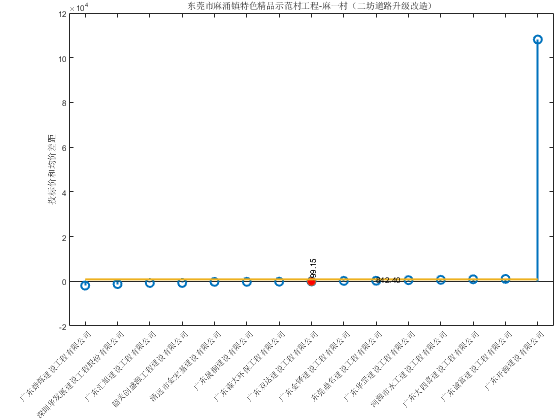

for i = 1:15
    sheet1.Range(['A', num2str(9 + i)]).Value = i;
    sheet1.Range(['B', num2str(9 + i)]).Value = company_name{i};
    sheet1.Range(['C', num2str(9 + i)]).Value = Gn(i);
    sheet1.Range(['D', num2str(9 + i)]).Value = Ps(i);
    sheet1.Range(['E', num2str(9 + i)]).Value = test_value(i);
    sheet1.Range(['F', num2str(9 + i)]).Value = zbxfl(i);

end

% 图形复制
hgexport(fig, '-clipboard');

% 图形粘贴
% 选中 sheet1 的 D3 单元格，插入直方图
sheet1.Range('G1').Select;
sheet1.Paste;  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 保存并关闭
workbook.Save;
workbook.Close;
excel.Quit;
% 打开 Excel
winopen(filename);